clear
trellis = poly2trellis(7,[115 147],147);
numframes = 1;
K = 20;
n = 700;
BlockLengthHalf = n;
Err_2=[]


Err_2 =

     []



place=zeros(1,20);
for snr=1:0.1:10
    error=zeros(1,1000);
    for k=1:100
        for j=1:K
            data{j} = randi([0 1],n,numframes,'int8');
        end
        for j=1:K
            codedData{j} = Code(data{j},trellis);
            cD1{j}=reshape(codedData{j},[2 BlockLengthHalf])';
        end
        input=pskmod(cD1{1}(:,1),2,0);
        for j=1:K-1
            input1 = bi2de([cD1{j}(:,2),cD1{j+1}(:,1)],"left-msb");
            input = [input;pskmod(input1,4,pi/4)];
        end
        input = [input;pskmod(cD1{K}(:,2),2,0)];
        output = awgn(input,snr);
        for j=1:K-1
            LLR1Half{j} = pskdemod(output(BlockLengthHalf*(j-1)+1:BlockLengthHalf*j),2,0,OutputType="llr");
            LLR2Half = reshape(pskdemod(output(BlockLengthHalf*j+1:BlockLengthHalf*(j+1)),4,pi/4,OutputType="llr"),[2 BlockLengthHalf])';
            LLR{j} = [LLR1Half{j},LLR2Half(:,1)];
            LlrActual=LLR{j}';
            decodedData{j} = Decode(LlrActual(:),trellis);
            EstimatedCodeword = Code(decodedData{j},trellis);
            EstimatedCodeword = reshape(EstimatedCodeword,[2 BlockLengthHalf])';
            SecondPartECWinFourier = pskmod(EstimatedCodeword(:,2),2,pi/2);
            output(BlockLengthHalf*j+1:BlockLengthHalf*(j+1))=output(BlockLengthHalf*j+1:BlockLengthHalf*(j+1))-1/sqrt(2)*SecondPartECWinFourier;    
        end
        LLR{K} = reshape(pskdemod(output(BlockLengthHalf*(20-1)+1:BlockLengthHalf*(20+1)),2,0,OutputType="llr"),[BlockLengthHalf 2]);
        LlrActual=LLR{K}';
        decodedData{K} = Decode(LlrActual(:),trellis);
        for j=1:K
            ErrCount(j)=biterr(data{j},decodedData{j});
        end
        error(k)=sum(ErrCount)/K;
        if ErrCount ~= 0
            [m,j]=max(ErrCount);
            place(j)=place(j)+1;
        end
    end
    Err_2(end+1)=mean(error)/n;
    snr
end

snr = 1

snr = 1.1000

snr = 1.2000

snr = 1.3000

snr = 1.4000

snr = 1.5000

snr = 1.6000

snr = 1.7000

snr = 1.8000

snr = 1.9000

snr = 2

snr = 2.1000

snr = 2.2000

snr = 2.3000

snr = 2.4000

snr = 2.5000

snr = 2.6000

snr = 2.7000

snr = 2.8000

snr = 2.9000

snr = 3

snr = 3.1000

snr = 3.2000

snr = 3.3000

snr = 3.4000

snr = 3.5000

snr = 3.6000

snr = 3.7000

snr = 3.8000

snr = 3.9000

snr = 4

snr = 4.1000

snr = 4.2000

snr = 4.3000

snr = 4.4000

snr = 4.5000

snr = 4.6000

snr = 4.7000

snr = 4.8000

snr = 4.9000

snr = 5

snr = 5.1000

snr = 5.2000

snr = 5.3000

snr = 5.4000

snr = 5.5000

snr = 5.6000

snr = 5.7000

snr = 5.8000

snr = 5.9000

snr = 6

snr = 6.1000

snr = 6.2000

snr = 6.3000

snr = 6.4000

snr = 6.5000

snr = 6.6000

snr = 6.7000

snr = 6.8000

snr = 6.9000

snr = 7

snr = 7.1000

snr = 7.2000

snr = 7.3000

snr = 7.4000

snr = 7.5000

snr = 7.6000

snr = 7.7000

snr = 7.8000

snr = 7.9000

snr = 8

snr = 8.1000

snr = 8.2000

snr = 8.3000

snr = 8.4000

snr = 8.5000

snr = 8.6000

snr = 8.7000

snr = 8.8000

snr = 8.9000

snr = 9

snr = 9.1000

snr = 9.2000

snr = 9.3000

snr = 9.4000

snr = 9.5000

snr = 9.6000

snr = 9.7000

snr = 9.8000

snr = 9.9000

snr = 10

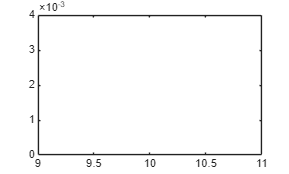

plot(snr,Err_2)

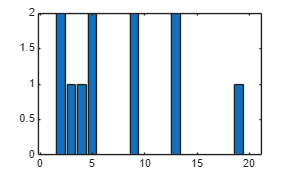

bar(place)


function output=Code(InfBits,Params)
    output = convenc(InfBits,Params);
end
function EstimatedInfBits=Decode(LogLikelihoodRation,Params)
    tbdepth = 60; % Traceback depth for Viterbi decoder
    EstimatedInfBits = vitdec(LogLikelihoodRation,Params,tbdepth,'trunc','unquant');
end